## Instructions: Enter your answers below each corresponding question header.

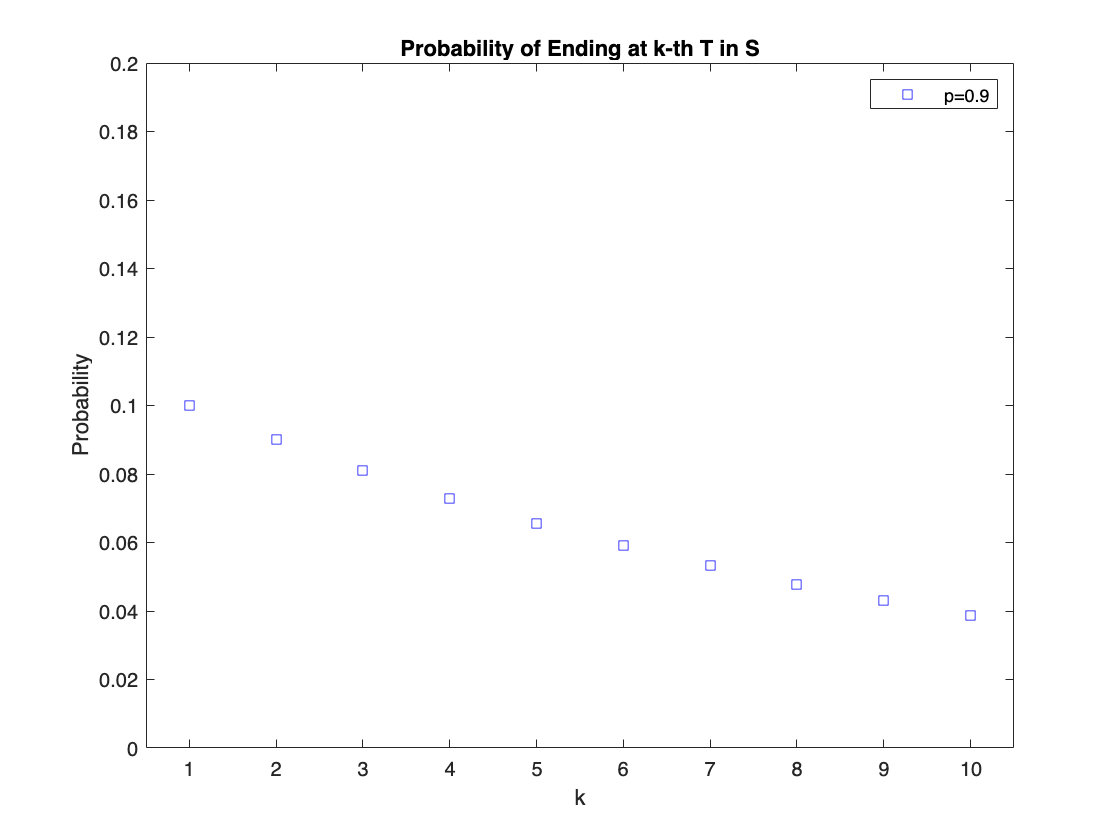

p = 0.9;

k = 1:10; 
pdf = geopdf(k-1, 1-p); 
plot(k, pdf, 'bs')

ylim([0, 0.2]) 
ylabel('Probability') 
xlim([0.5 10.5]) 
xticks(1:10) 
xlabel('k') 
legend('p=0.9') 
title('Probability of Ending at k-th T in S')

## Q1

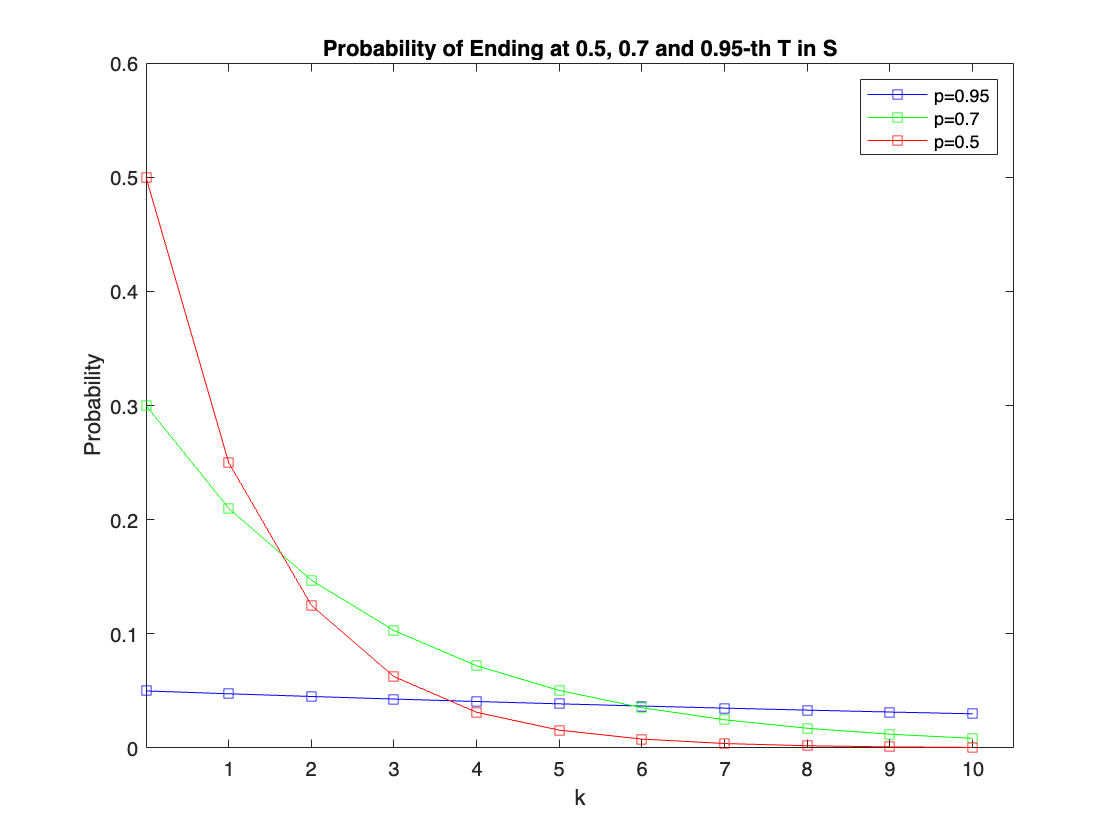

figure; 
k = 0:10;
pdf_95 = geopdf(k, 1-0.95);
pdf_70 = geopdf(k, 1-0.7);
pdf_50 = geopdf(k, 1-0.5);

plot(k, pdf_95, '-bs');
hold on; 
plot(k, pdf_70, '-gs');
plot(k, pdf_50, '-rs');
hold off

ylim([0, 0.6]);
ylabel('Probability');
xlim([0 10.5]);
xticks(1:10);
xlabel('k');
legend('p=0.95','p=0.7','p=0.5');
title('Probability of Ending at 0.5, 0.7 and 0.95-th T in S');

## Q2

k = 10;

P_95 = geopdf(k, 1 - 0.95);  % p = 0.95
P_70 = geopdf(k, 1 - 0.7);  % p = 0.7
P_50 = geopdf(k, 1 - 0.5);  % p = 0.5

% Displaying the results
fprintf('P(k=10 | p=0.95) = %.4f\n', P_95);

P(k=10 | p=0.95) = 0.0299


fprintf('P(k=10 | p=0.7) = %.4f\n', P_70);

P(k=10 | p=0.7) = 0.0085


fprintf('P(k=10 | p=0.5) = %.4f\n', P_50);

P(k=10 | p=0.5) = 0.0005


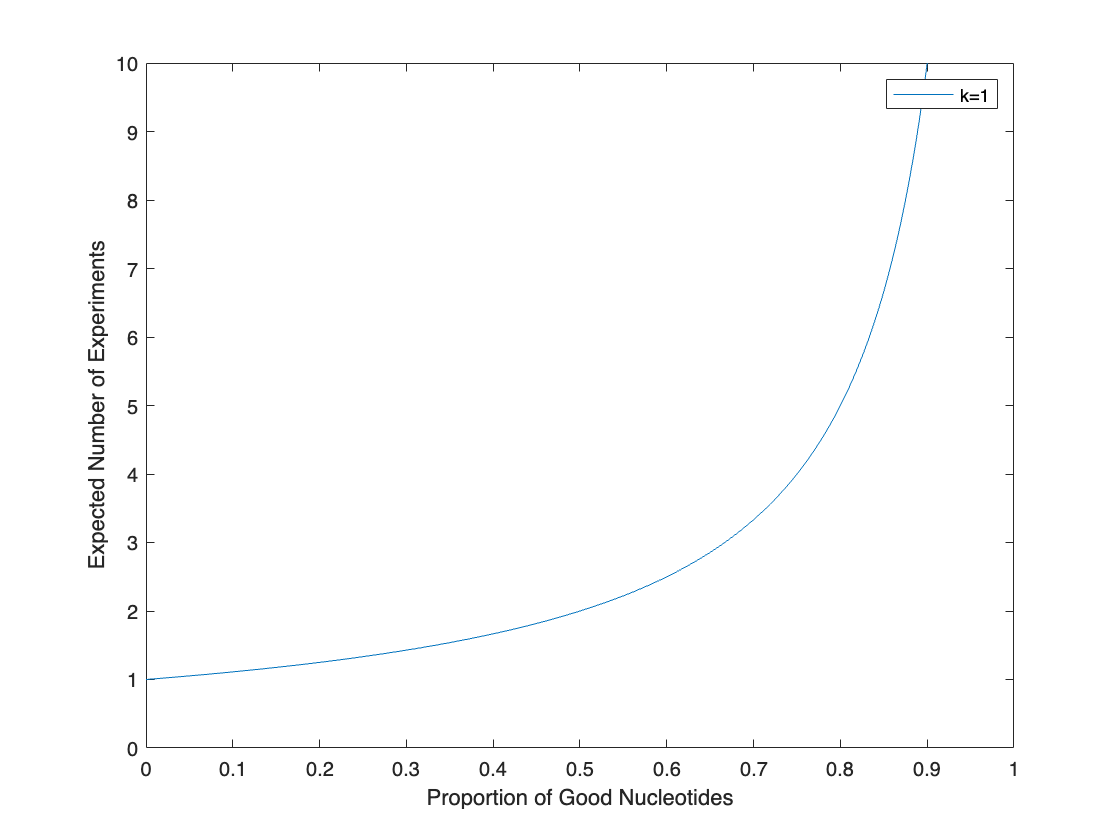

p = 0:0.001:1; 
k = 1;

n_exp_1 = 1./geopdf(k-1, 1-p);

plot(p, n_exp_1) 
xlim([0 1]) 
xlabel('Proportion of Good Nucleotides') 
ylabel('Expected Number of Experiments') 
ylim([0 10]) 
legend('k=1')

## Q4

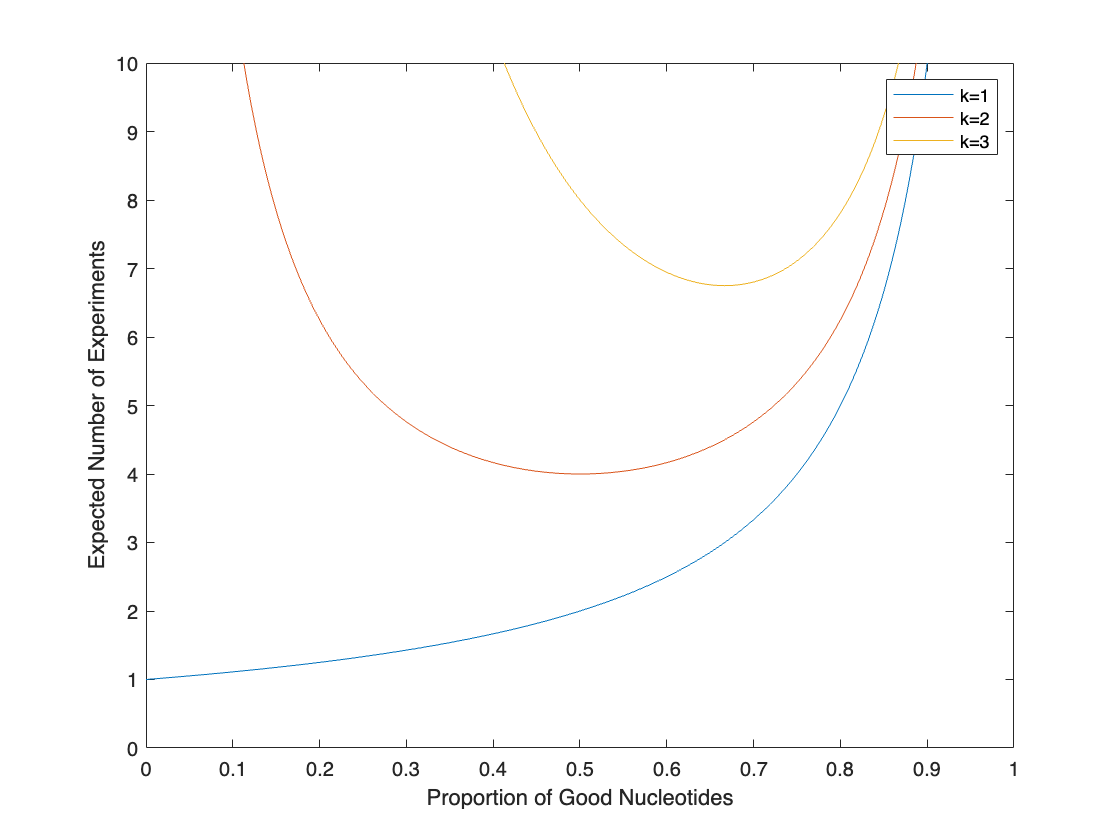

figure; 
p = 0:0.001:1;
n_exp_1 = 1./geopdf(0, 1-p);
n_exp_2 = 1./geopdf(1, 1-p);
n_exp_3 = 1./geopdf(2, 1-p);

plot(p, n_exp_1);
hold on; 
plot(p, n_exp_2)
plot(p, n_exp_3)
hold off;
xlim([0 1])
xlabel('Proportion of Good Nucleotides')
ylabel('Expected Number of Experiments')
ylim([0 10])
legend('k=1','k=2','k=3')

## Q6

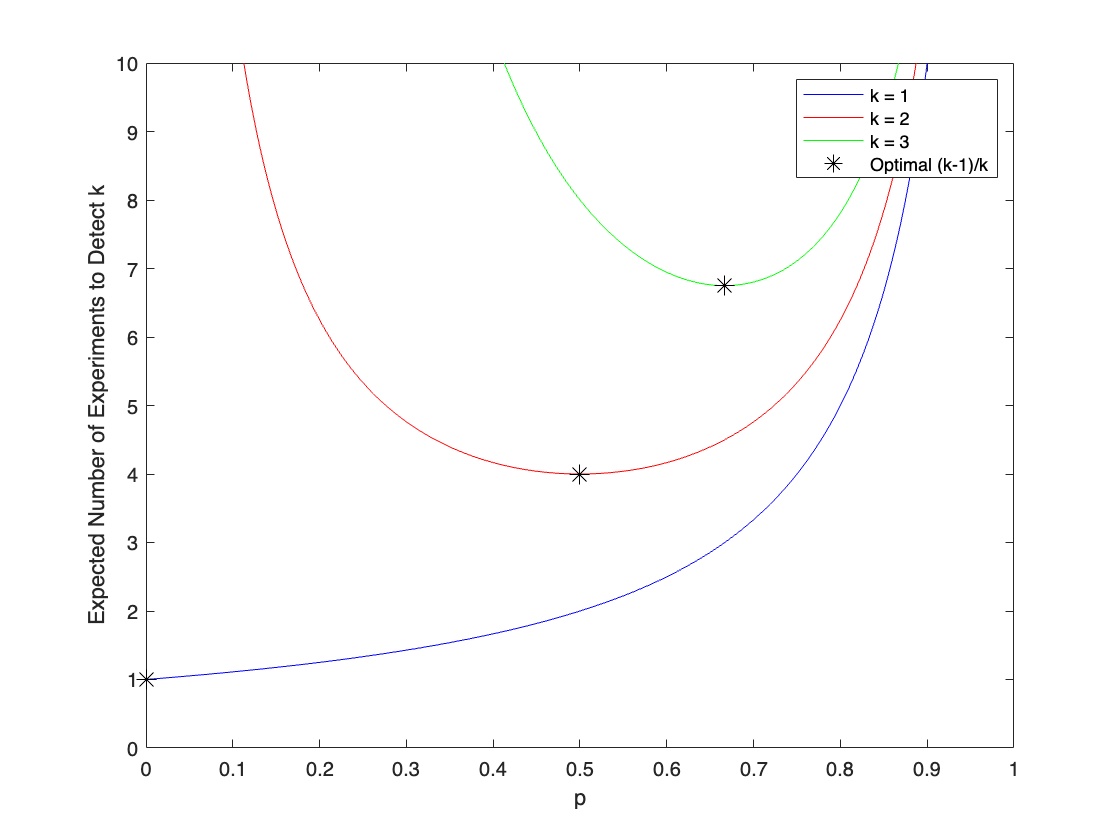

p = 0:0.001:1;
k = 1:3;
p_opt = (k-1)./k;
n_opt = [1./geopdf(0, 1-p_opt(1)),...
         1./geopdf(1, 1-p_opt(2)),...
         1./geopdf(2, 1-p_opt(3))];

n_exp_1 = 1./geopdf(0, 1-p); 
n_exp_2 = 1./geopdf(1, 1-p); 
n_exp_3 = 1./geopdf(2, 1-p); 

figure(3) 
hold on; 

h1 = plot(p, n_exp_1, 'b'); % Assign color blue
h2 = plot(p, n_exp_2, 'r'); % Assign color red
h3 = plot(p, n_exp_3, 'g'); % Assign color green
h4 = plot(p_opt, n_opt, 'k*', 'MarkerSize', 10); % Assign color black with marker *

hold off;

xlim([0 1]) 
ylim([0 10]) 
xlabel('p') 
ylabel('Expected Number of Experiments to Detect k')
legend([h1 h2 h3 h4], {'k = 1', 'k = 2', 'k = 3', 'Optimal (k-1)/k'});

## Q7

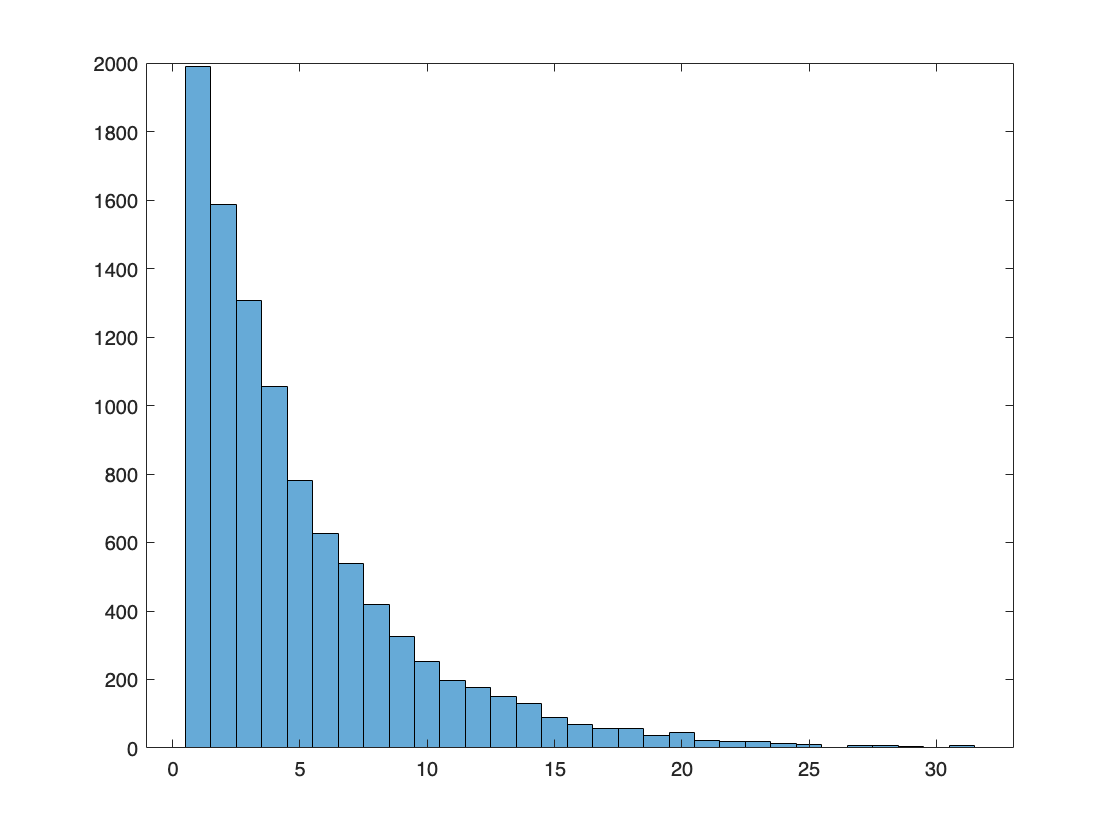

figure;
p = 0.5;
Nk = 30;
N_experiments = 100;
outcomes = NaN(N_experiments, 1); 
for i = 1:N_experiments
outcomes(i) = min([geornd(1-p)+1, Nk+1]);
end

figure;
p = 0.8;
Nk = 30;
N_experiments = 10000;
outcomes = NaN(N_experiments, 1);
for i = 1:N_experiments
outcomes(i) = min([geornd(1-p)+1, Nk+1]);
end
histogram(outcomes)

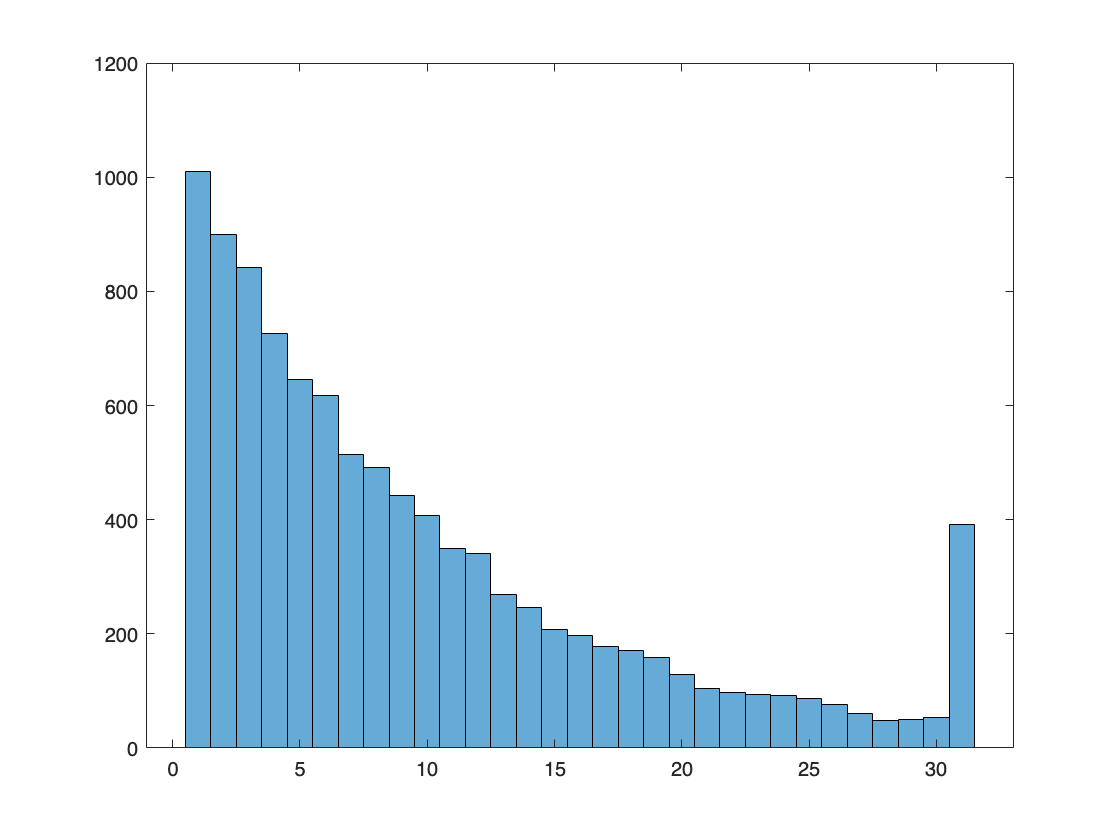

figure;
p = 0.9;
Nk = 30;
N_experiments = 10000;
outcomes = NaN(N_experiments, 1);
for i = 1:N_experiments
outcomes(i) = min([geornd(1-p)+1, Nk+1]);
end
histogram(outcomes)


questions.q7 = "Answer.";


## Q8

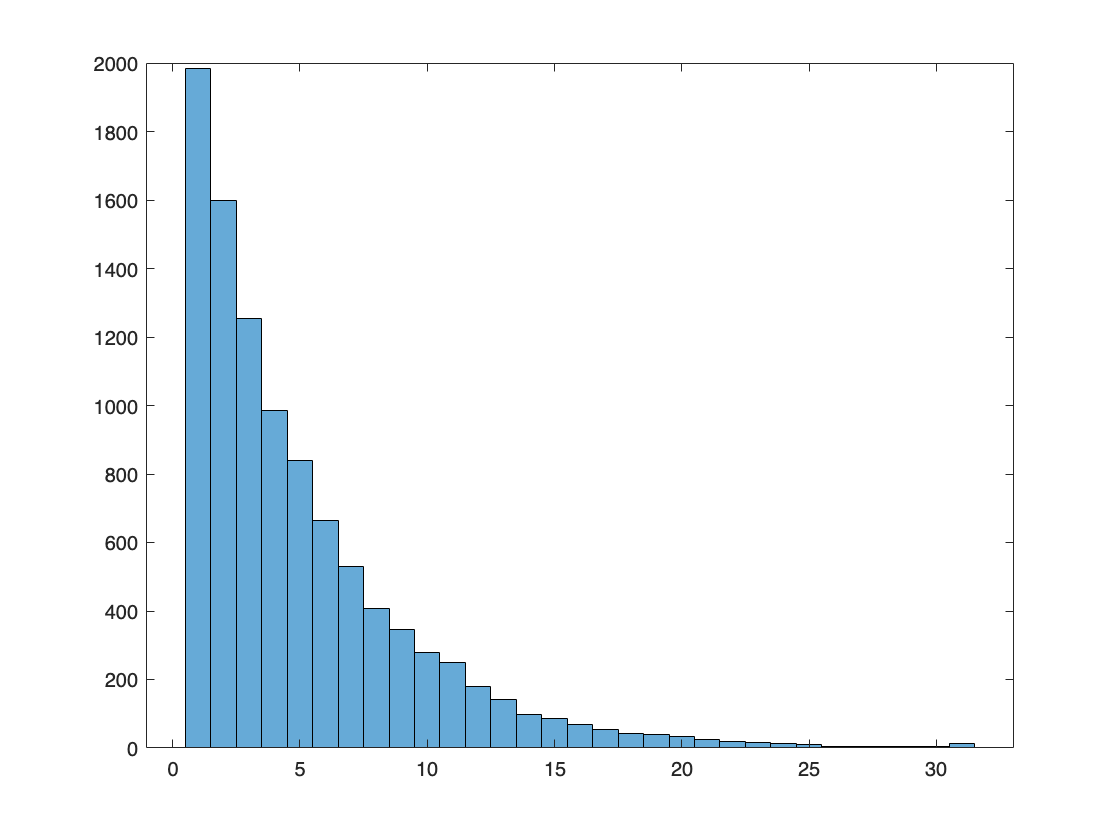

figure;
p = 0.8;
Nk = 30;
N_experiments = 10000;
outcomes = NaN(N_experiments, 1);
for i = 1:N_experiments
outcomes(i) = min([geornd(1-p)+1, Nk+1]);
end
histogram(outcomes)

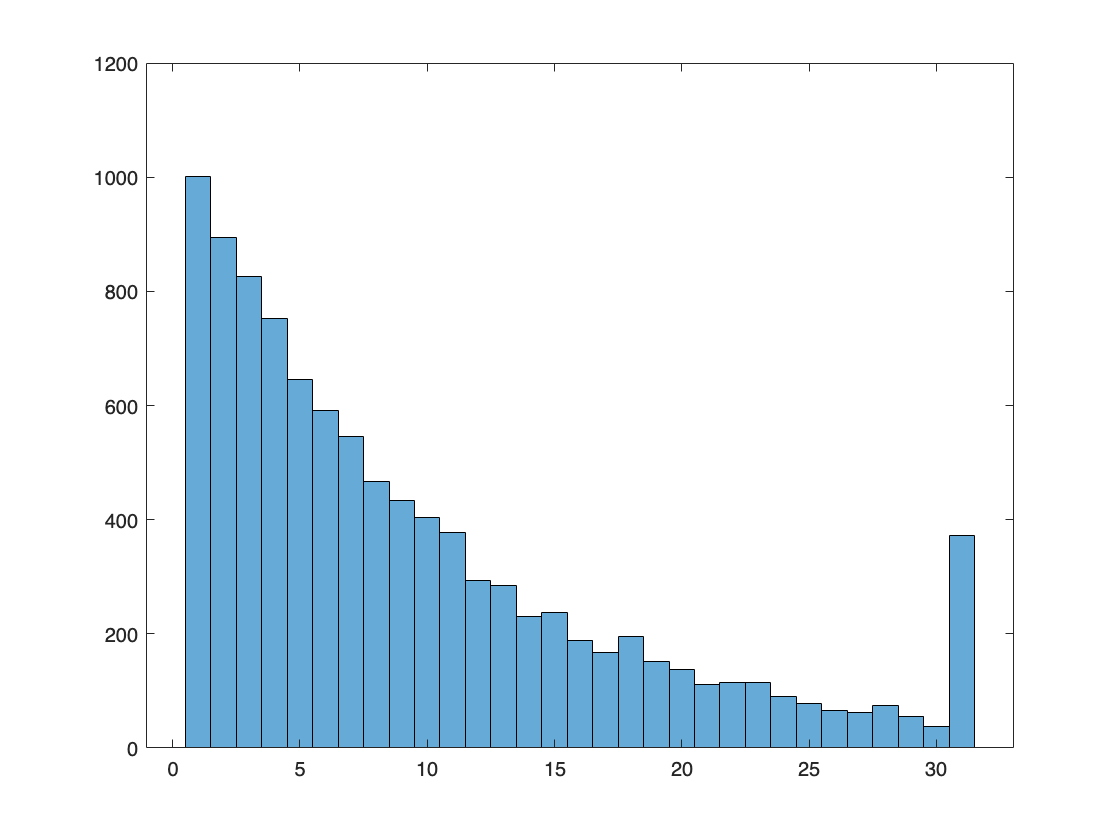


figure;
p = 0.9;
Nk = 30;
N_experiments = 10000;
outcomes = NaN(N_experiments, 1);
for i = 1:N_experiments
outcomes(i) = min([geornd(1-p)+1, Nk+1]);
end
histogram(outcomes)

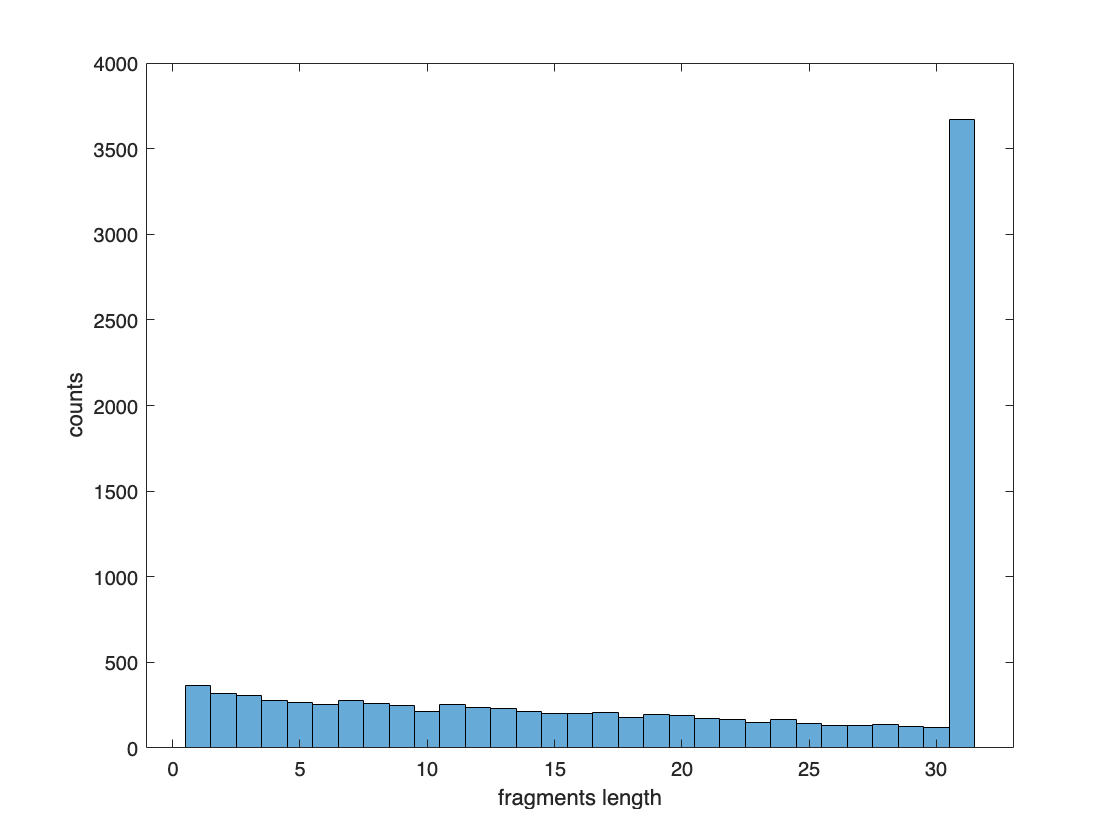


Nk = 30;
p = (Nk-1)/Nk;
N_experiments = 10000;
outcomes = NaN(N_experiments, 1);
for i = 1:N_experiments
outcomes(i) = min([geornd(1-p)+1, Nk+1]);
end
histogram(outcomes)
xlabel('fragments length')
ylabel ('counts')


questions.q8 = "Answer.";


## Q9

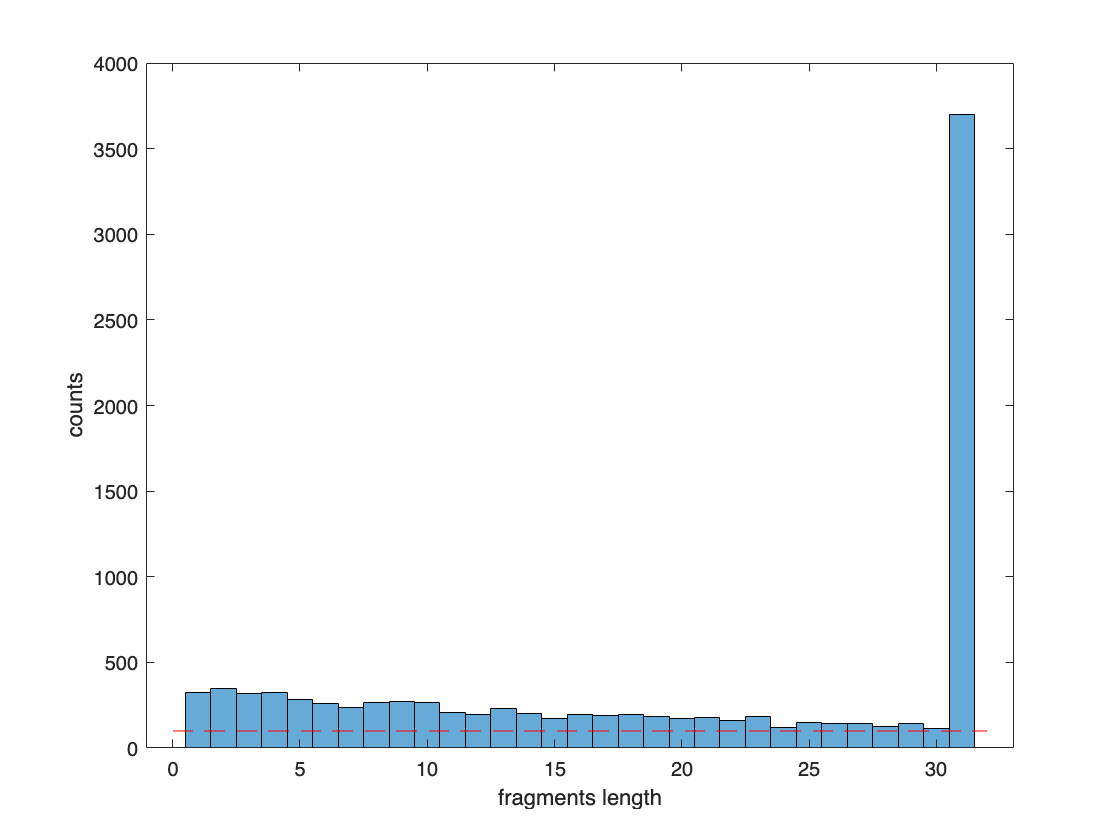

figure;
Nk = 30;  % Length of the DNA sequence
p = (Nk-1)/Nk;  % Proportion of good nucleotides
N_experiments = 10000;
outcomes = NaN(N_experiments, 1);
for i = 1:N_experiments
outcomes(i) = min([geornd(1-p)+1, Nk+1]);
end
histogram(outcomes)
hold on 

plot([0,32],[100,100],'--r')
xlabel('fragments length')
ylabel ('counts')

questions.q9 = "Answer.";
disp(questions);

    q4: "See graph."
    q5: "Answer."
    q6: "Answer."
    q7: "Answer."
    q8: "Answer."
    q9: "Answer."

